%DEMO_ART Demonstrates the use of, and results from, the ART methods
%
% This script illustrates the use of the ART methods Kaczmarz, symmetric
% Kaczmarz, and randomized Kaczmarz.
%
% The script creates a parallel-beam CT test problem and solves it with the
% ART methods.  The exact image and the results from the methods are shown.
%
% See also: demo_cart, demo_constraints, demo_custom_all, demo_matrixfree,
% demo_relaxpar, demo_sirt, demo_stoprules, demo_training.

% Code written by: Per Christian Hansen, Jakob Sauer Jorgensen, and
% Maria Saxild-Hansen, 2010-2017.

% This file is part of the AIR Tools II package and is distributed under
% the 3-Clause BSD License. A separate license file should be provided as
% part of the package.
%
% Copyright 2017 Per Christian Hansen, Technical University of Denmark and
% Jakob Sauer Jorgensen, University of Manchester.

clear, clc
fprintf(1,'Starting demo_art:\n\n');

Starting demo_art:




% Set the parameters for the test problem.
N = 50;           % The image is N-times-N..
phi = 0:2:178;  % No. of used angles.
p = 75;           % No. of parallel rays.

fprintf(1,'Creating a parallel-beam tomography test problem\n');

Creating a parallel-beam tomography test problem


fprintf(1,'with N = %2.0f, theta = %1.0f:%1.0f:%3.0f, and p = %2.0f.',...
    [N,phi(1),phi(2)-phi(1),phi(end),p]);

with N = 50, theta = 0:2:178, and p = 75.

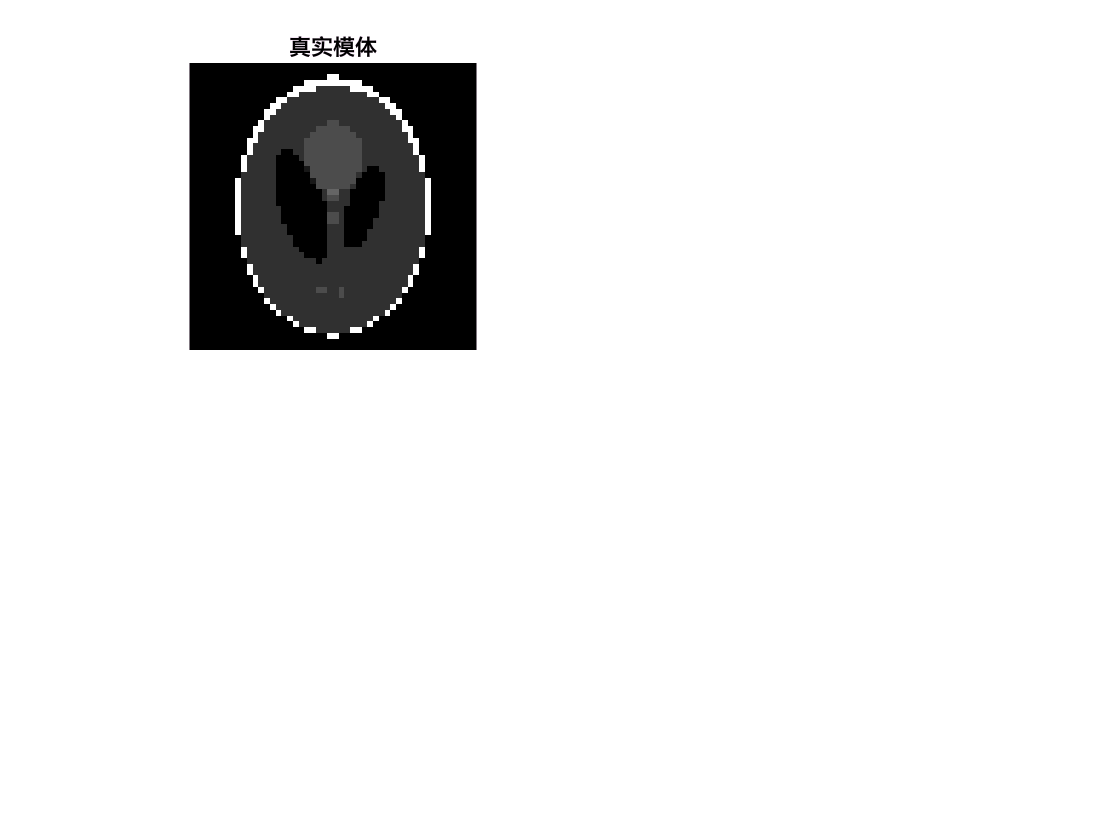


% Create the test problem.
[A,b,x] = paralleltomo(N,phi,p);

% Show the exact solution.
figure(1), clf
% subplot()
subplot(2,2,1)
imagesc(reshape(x,N,N)), colormap gray, axis image off
c = caxis;
title('真实模体')

fprintf(1, 'sparsity: %d', sum(x == 0))

sparsity: 1482

fprintf(1,'\n\n');


x0 = zeros(N ^ 2, 1);

## Necessary calculation for RSK

% tic
% cov_A = cov(A); % expensive
% eig_cov_A = eig(cov_A); % expensive too!
% min_eig = min(eig_cov_A(eig_cov_A > 0));
% ita = @(t, theta) (1 + t * min_eig) ^ (-theta);
% toc  % approx 4 min


## Iteration settings

geometric_seq = @(max) 2.^(0:floor(log2(max)));
k = geometric_seq(512);
% k = geometric_seq(16);
lambda = 1

lambda = 1

small_noise_std = 0.01;
large_noise_std = 0.1;
% k = [1:1:10 11:2:30 31:4:70 72:8:130 134:12:256];
ita = @(t, theta, speed) (1 + speed * t) ^ (-theta);
% run_special = @(type) art(type,A,b,k,x0,struct('waitbar',true, 'lambda', lambda));
% run_special_gaussian = @(type, speed) art(type,A,b,k,x0,struct('waitbar',true, 'noise','gaussian', 'speed', speed, 'lambda', lambda));
% run_special_cauchy = @(type, speed) art(type,A,b,k,x0,struct('waitbar',true, 'noise','cauchy', 'speed', speed, 'lambda', lambda));
run_general = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'speed', speed, 'lambda', lambda));
run_robust = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'robust', true, 'speed', speed, 'lambda', lambda));
run_general_gaussian = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'noise','gaussian', 'speed', speed, 'lambda', lambda, 'noise_std', large_noise_std));
run_robust_gaussian = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'robust', true, 'noise','gaussian', 'speed', speed, 'lambda', lambda, 'noise_std', large_noise_std));
run_general_small_gaussian = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'noise','gaussian', 'speed', speed, 'lambda', lambda, 'noise_std', small_noise_std));
run_robust_small_gaussian = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'robust', true, 'noise','gaussian', 'speed', speed, 'lambda', lambda, 'noise_std', small_noise_std));
run_general_cauchy = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'noise','cauchy', 'speed', speed, 'lambda', lambda));
run_robust_cauchy = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'robust', true, 'noise','cauchy', 'speed', speed, 'lambda', lambda));
plotter = Plotter(x, N, c, k, A);

## Perform the Kaczmarz iterations.

% type = 'kaczmarz';
% [Xrand, info] = run_special(type);
% plotter.plot(Xrand, type);

## Perform the randomized Kaczmarz iterations.

相对误差下降至 3.943835 %


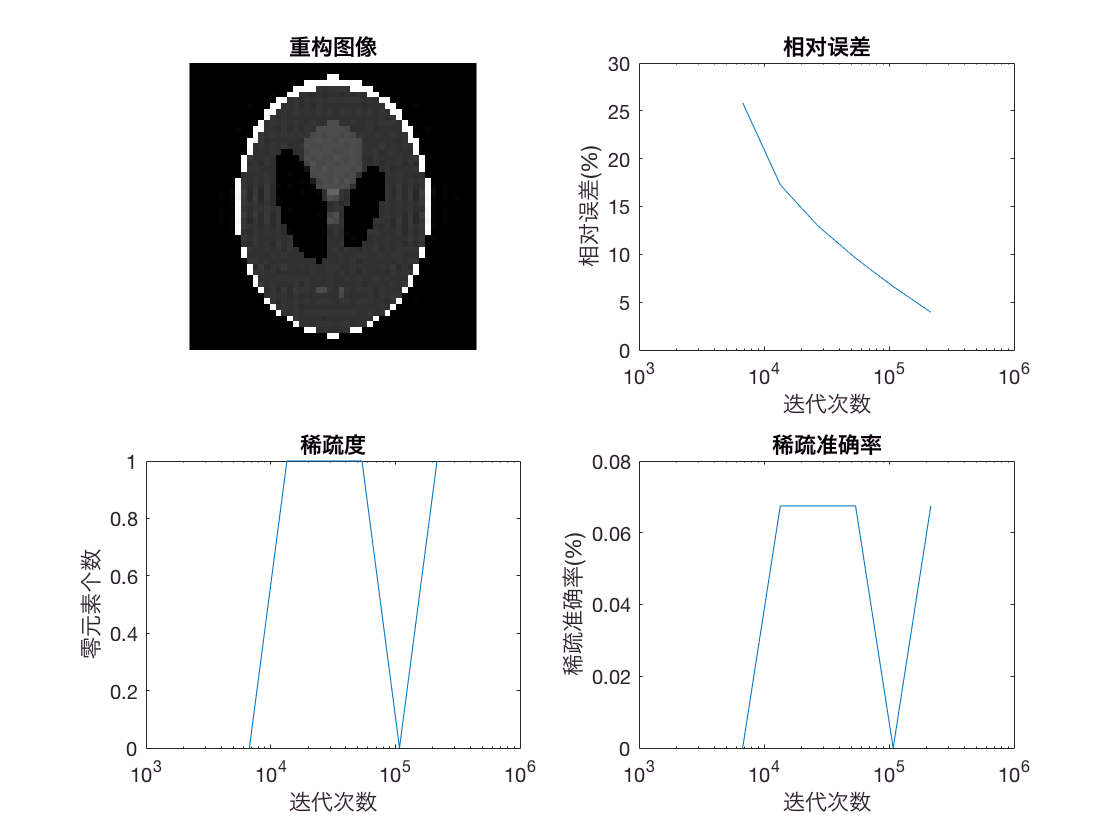

type = 'randkaczmarz';
[Xrand, info] = run_special(type);
plotter.plot(Xrand);

## SK

相对误差下降至 2.819856 %


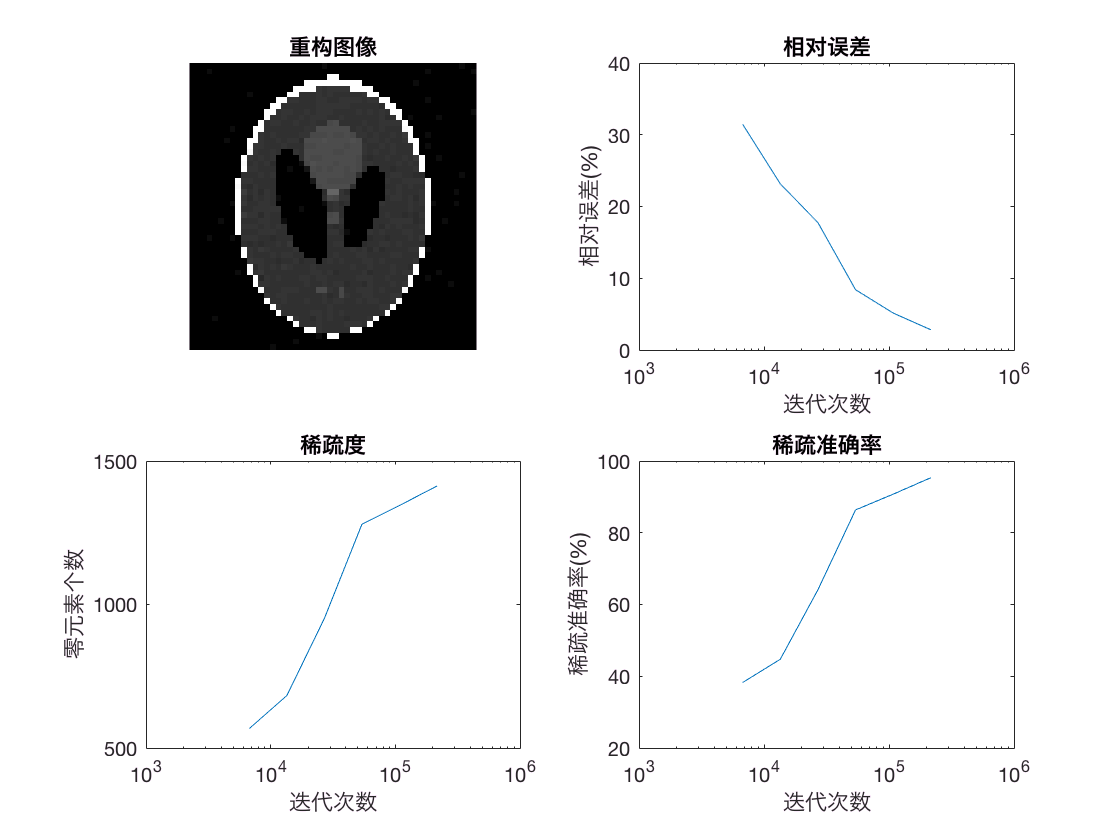

type = 'SK';
[Xrand, info] = run_special(type);
plotter.plot(Xrand);

## The special RSK in [26]

% [Xrand, info] = run_general('RSK', 0, 5e-6);
% plotter.plot(Xrand)

## Generalized RSK

[Xrand, info] = run_general('RSK',1, 5e-6);

ita decayed to 0.685605 by speed 0.000005 in the end


相对误差下降至 0.067819 %


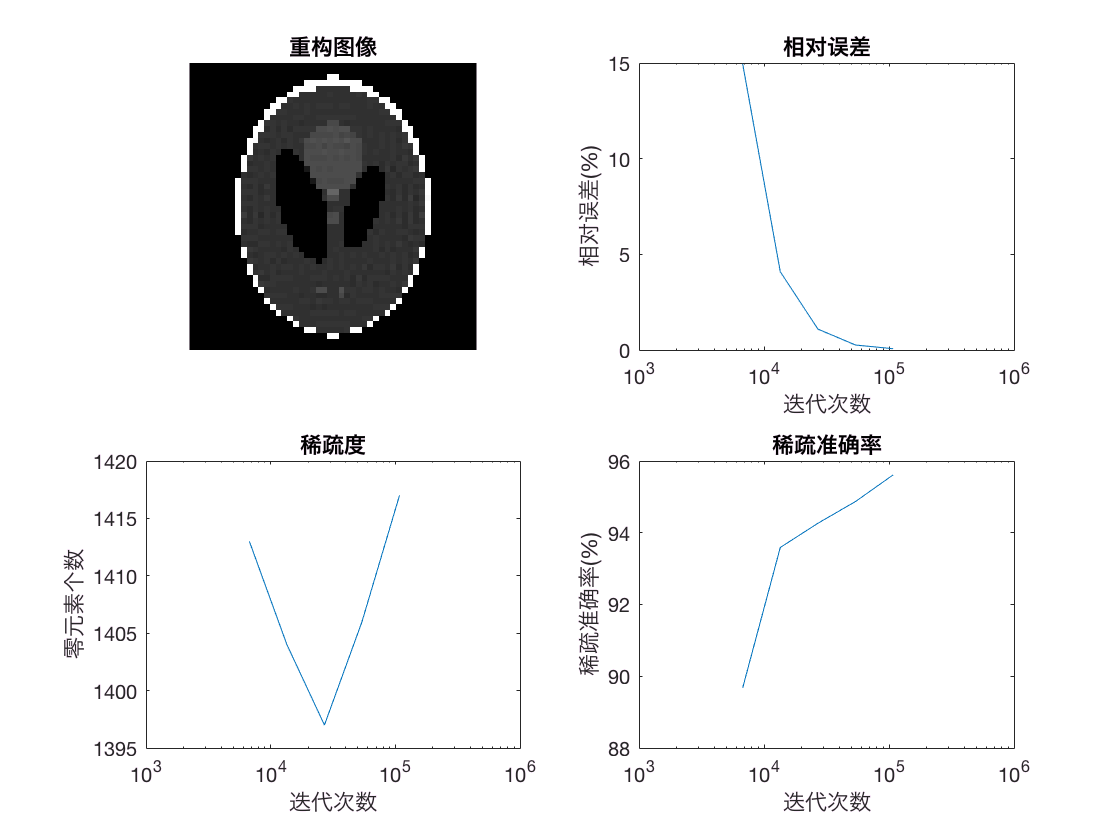

plotter.plot(Xrand)

## Generalized RSK with theta = 0.5 

% [Xrand, info] = run_general('RSK',0.5, 5e-6);
% plotter.plot(Xrand)

## Robust RSK

[Xrand, info] = run_robust('RSK',1 , 5e-6);

ita decayed to 0.352828 by speed 0.000005 in the end


相对误差下降至 0.202821 %


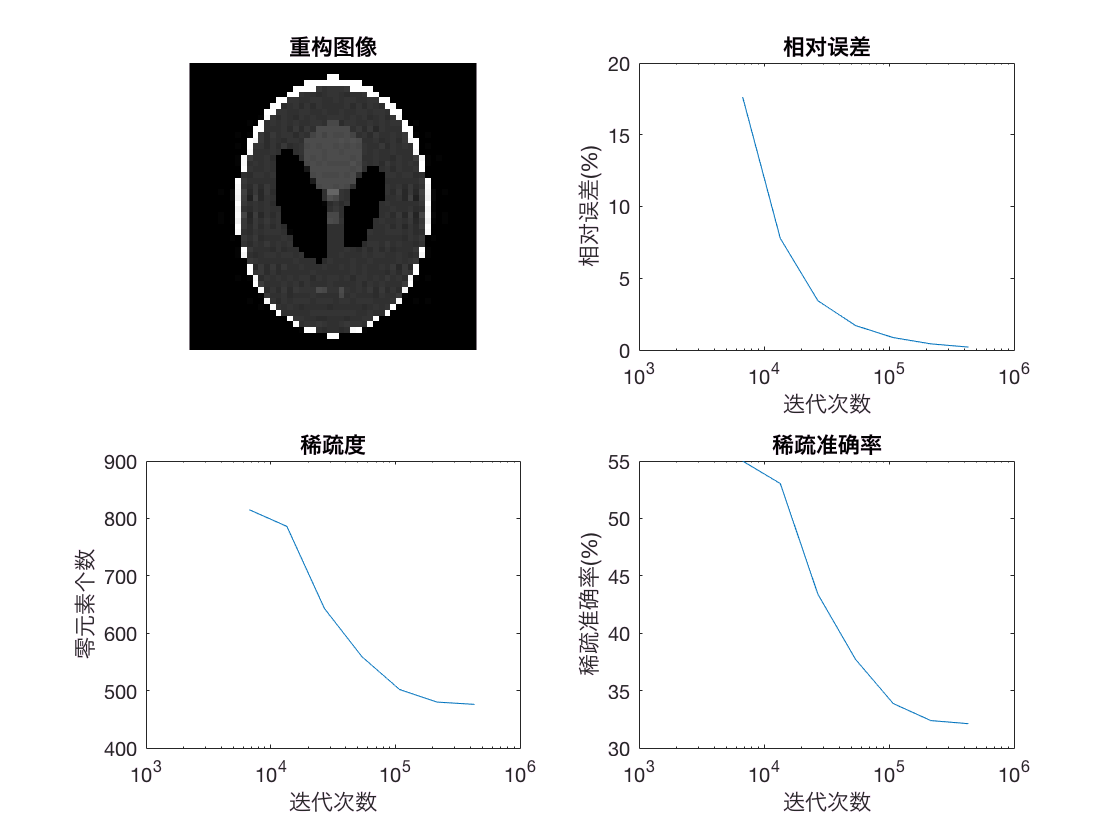

plotter.plot(Xrand)

%% Generalized RSK under Gaussian Noise

% [Xrand, info] = run_general_gaussian('RSK',1, 5e-6);
% plotter.plot(Xrand)

%% Robust RSK under Gaussian Noise

% [Xrand, info] = run_robust_gaussian('RSK',1, 5e-6);
% plotter.plot(Xrand)

%% Generalized RSK under Cauchy Noise

% [Xrand, info] = run_general_cauchy('RSK',1, 5e-6);
% plotter.plot(Xrand)

%% Robust RSK under Cauchy Noise

% [Xrand, info] = run_robust_cauchy('RSK',1, 5e-6);
% plotter.plot(Xrand)

%% compare without Noise

[X_RSK0, info] = run_general('RSK',0, 5e-6);

Reference to non-existent field 'noise_std'.

Error in check_inputs (line 294)
    noise_std = options.noise_std;

Error in art (line 120)
     damp,~,~,~,lambda,ita,theta,robust,noise,speed,noise_std] = check_inputs(varargin{:});

Error in demo_art>@(

[X_RSK1, info] = run_general('RSK',1, 5e-6);
[X_RRSK, info] = run_robust('RSK',1, 5e-6);
plotter.plot(X_RSK0)
plotter.plot(X_RSK1)
plotter.plot(X_RRSK)
plotter.compare({'RSK0', 'RSK1', 'RRSK'}, X_RSK0, X_RSK1, X_RRSK)

%% compare under Gaussian Noise

[X_RSK0, info] = run_general_gaussian('RSK',0, 5e-6);
[X_RSK1, info] = run_general_gaussian('RSK',1, 5e-6);
[X_RRSK, info] = run_robust_gaussian('RSK',1, 5e-6);
plotter.plot(X_RSK0)
plotter.plot(X_RSK1)
plotter.plot(X_RRSK)
plotter.compare({'RSK0', 'RSK1', 'RRSK'}, X_RSK0, X_RSK1, X_RRSK)


%% compare under small Gaussian Noise

[X_RSK0, info] = run_general_small_gaussian('RSK',0, 5e-6);
[X_RSK1, info] = run_general_small_gaussian('RSK',1, 5e-6);
[X_RRSK, info] = run_robust_small_gaussian('RSK',1, 5e-6);
plotter.plot(X_RSK0)
plotter.plot(X_RSK1)
plotter.plot(X_RRSK)
plotter.compare({'RSK0', 'RSK1', 'RRSK'}, X_RSK0, X_RSK1, X_RRSK)

%% compare under Cauchy Noise

[X_RSK0, info] = run_general_cauchy('RSK',0, 5e-6);
[X_RSK1, info] = run_general_cauchy('RSK',1, 5e-6);
[X_RRSK, info] = run_robust_cauchy('RSK',1, 5e-6);
plotter.plot(X_RSK0)
plotter.plot(X_RSK1)
plotter.plot(X_RRSK)
plotter.compare({'RSK0', 'RSK1', 'RRSK'}, X_RSK0, X_RSK1, X_RRSK)


## calculate std of each method for cauchy & gaussian noise

repetition = 5;
relative_errors = zeros(repetition, 3);
for i = 1:repetition
    [X_RSK0, info] = run_general_cauchy('RSK',0, 5e-6);
    relative_error = evaluate(x, X_RSK0);
    relative_errors(i, 1) = relative_error(end);
    [X_RSK1, info] = run_general_cauchy('RSK',1, 5e-6);
    relative_error = evaluate(x, X_RSK1);
    relative_errors(i, 2) = relative_error(end);
    [X_RRSK, info] = run_robust_cauchy('RSK',1, 5e-6);
    relative_error = evaluate(x, X_RRSK);
    relative_errors(i, 3) = relative_error(end);
    
    [X_RSK0, info] = run_general_gaussian('RSK',0, 5e-6);
    relative_error = evaluate(x, X_RSK0);
    relative_errors(i, 4) = relative_error(end);
    [X_RSK1, info] = run_general_gaussian('RSK',1, 5e-6);
    relative_error = evaluate(x, X_RSK1);
    relative_errors(i, 5) = relative_error(end);
    [X_RRSK, info] = run_robust_gaussian('RSK',1, 5e-6);
    relative_error = evaluate(x, X_RRSK);
    relative_errors(i, 6) = relative_error(end);
    
    [X_RSK0, info] = run_general_small_gaussian('RSK',0, 5e-6);
    relative_error = evaluate(x, X_RSK0);
    relative_errors(i, 7) = relative_error(end);
    [X_RSK1, info] = run_general_small_gaussian('RSK',1, 5e-6);
    relative_error = evaluate(x, X_RSK1);
    relative_errors(i, 8) = relative_error(end);
    [X_RRSK, info] = run_robust_small_gaussian('RSK',1, 5e-6);
    relative_error = evaluate(x, X_RRSK);
    relative_errors(i, 9) = relative_error(end);
    
    [X_RSK0, info] = run_general('RSK',0, 5e-6);
    relative_error = evaluate(x, X_RSK0);
    relative_errors(i, 10) = relative_error(end);
    [X_RSK1, info] = run_general('RSK',1, 5e-6);
    relative_error = evaluate(x, X_RSK1);
    relative_errors(i, 11) = relative_error(end);
    [X_RRSK, info] = run_robust('RSK',1, 5e-6);
    relative_error = evaluate(x, X_RRSK);
    relative_errors(i, 12) = relative_error(end);
end
relative_errors_mean = mean(relative_errors)
relative_errors_std = std(relative_errors)


## grasp a feeling of the convergence speed

[X_RRSK, info] = run_robust_cauchy('RSK',1, 5e-6);
loss_4 = sum((x - X_RRSK).^2, 1);
[X_RRSK, info] = run_robust_cauchy('RSK',0.75, 5e-6);
loss_3 = sum((x - X_RRSK).^2, 1);
[X_RRSK, info] = run_robust_cauchy('RSK',0.5, 5e-6);
loss_2 = sum((x - X_RRSK).^2, 1);
[X_RRSK, info] = run_robust_cauchy('RSK',0.25, 5e-6);
loss_1 = sum((x - X_RRSK).^2, 1);
hold on
plot(loss_4./k.^(-1/4))